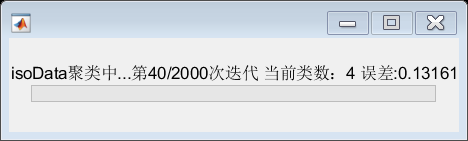

clear all;
clc;

% 导入图像
IMG=im2double(imread('C:\Users\L\Desktop\模式识别\input\beijing.tif'))*255;
row = length(IMG(:,1,:));   %图像排数
col = length(IMG(1,:,:));   %图像列数
bds = size(IMG,3);   %图像波段数

% 设置参数(k均值)
nClass = 5;
MK_error = 1e-3;

% 设置参数（isoData）
C = 4;
K = 5;
theta_N=5000;
theta_s=20;
theta_c=10;
L = 5;
I = 2000;
c_rate = 0.9;



% 显示灰度图像
gray = mean(IMG,3)/255;

figure;
imshow(gray);
title('灰度图');

res_pic = zeros(row,col,3);

% 数据打包
tic;  
Data = zeros(col*row, bds+2);
for x = 1:row
    for y = 1:col
        bands = reshape(IMG(x,y,:),[1,bds]);
        data = [x,y,bands];
        Data(row*(y-1) + x,:) = data;
    end
end

% 进行分类
[cluster2,~,C_isoData] = IsoData(Data,C, K,theta_N, theta_s, theta_c, L, I, c_rate, MK_error);

[cluster,~,~] = KMeans(Data,nClass,MK_error);

% 随机选择颜色
if nClass ~= 5
    colors = add_rand_color(nClass);
else
    colors =[0	0	0.70443;%water
        0.45 0.95474	0.45;%tree
        0.61181	0	0;%ground
        0	0.45706	0.56407;% city
        0.36753	0	0.4835];% road
end

if C_isoData ~= 5
    colors2 = add_rand_color(C_isoData);
else
    colors2 =[0	0	0.70443;%water
        0.45 0.95474	0.45;%tree
        0.61181	0	0;%ground
        0	0.45706	0.56407;% city
        0.36753	0	0.4835];% road
end

% 染色
bar = waitbar(0,'k均值染色中...');  
for class = 1:nClass
    if isempty(cluster(class).data)
        continue
    end
    result = cluster(class).data;
    
% %     截断全0行
%     result(all(result==0,2),:) = [];
    
    X = result(:,1);
    Y = result(:,2);
    
    for i = 1:length(X)
        x = X(i);
        y = Y(i);
        
        res_pic(x,y,:) = colors(class,:);
    end
    
    % 输出
    str=['k均值染色中...',num2str(class*100/nClass),'%'];

    waitbar(class/nClass,bar,str);
end
close(bar);

toc;

% 染色
iso_pic = zeros(row,col,3);
bar = waitbar(0,'isoData染色中...');  
for class = 1:C_isoData
    if isempty(cluster2(class).data)
        continue
    end
    result = cluster2(class).data;
    
    X = result(:,1);
    Y = result(:,2);
    
    for i = 1:length(X)
        x = X(i);
        y = Y(i);
        
        iso_pic(x,y,:) = colors2(class,:);
    end
    
    % 输出
    str=['isoData染色中...',num2str(class*100/C_isoData),'%'];

    waitbar(class/C_isoData,bar,str);
end
close(bar);

toc;

figure;
imshow(add_Color_bar(res_pic, colors));
title('k均值聚类结果');

figure;
imshow(add_Color_bar(iso_pic, colors2));
title('isoData聚类结果');
% imwrite(res_pic,'result.jpg');